plot the ecg signal

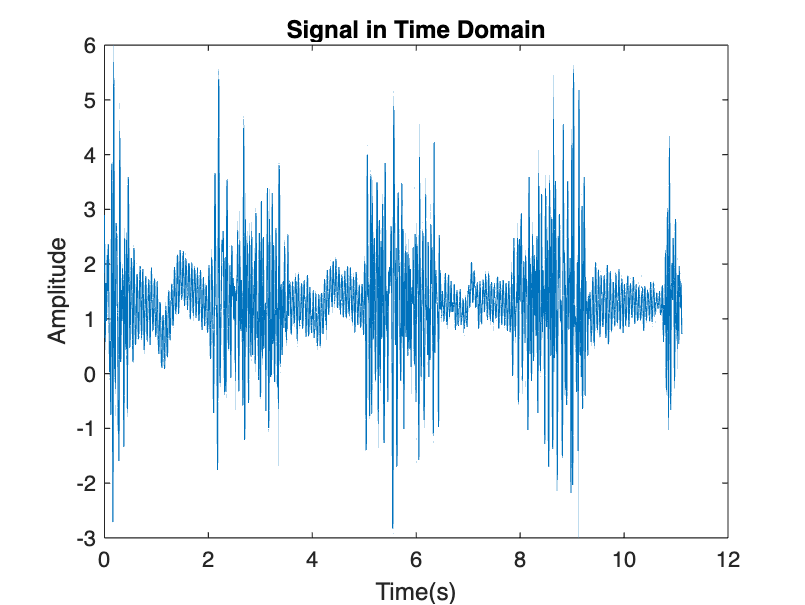

load('emg.mat');

fs = 360; %Hz
t=linspace(0,length(emg)/fs,length(emg));
figure()
plot(t,emg);
title('Signal in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');


figure()
f=linspace(-fs/2,fs/2,length(emg));
fft_emg = fftshift(abs(fft(emg))) % FFT of EMG signal

fft_emg = 1.0e+03 *

    0.0015    0.0030    0.0023    0.0015    0.0010    0.0019    0.0008    0.0026    0.0017    0.0028    0.0030    0.0015    0.0012    0.0014    0.0020    0.0013    0.0017    0.0019    0.0035    0.0006    0.0033    0.0029    0.0007    0.0026    0.0013    0.0019    0.0030    0.0023    0.0006    0.0028    0.0016    0.0023    0.0007    0.0027    0.0032    0.0033    0.0013    0.0048    0.0009    0.0007    0.0028    0.0038    0.0012    0.0047    0.0029    0.0048    0.0008    0.0024    0.0010    0.0016


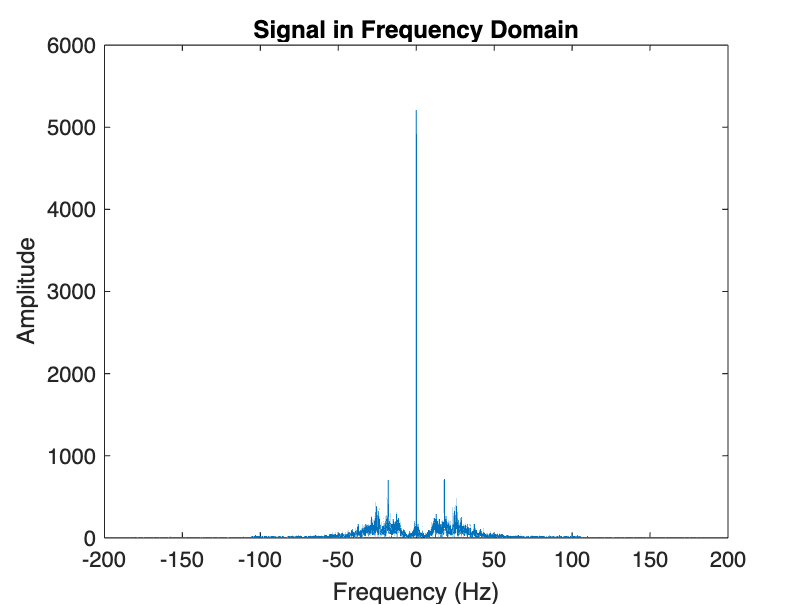


plot(f,fft_emg);
title('Signal in Frequency Domain'); 
xlabel('Frequency (Hz)');
ylabel('Amplitude');

dallo spettro del segnale si nota un picco a +-60 Hz, potrebbe essere un artefatto da strumentazione.

si può rimuovere con un filtro IIR stop-band centrato in 60 Hz.

plotto adesso ecg1

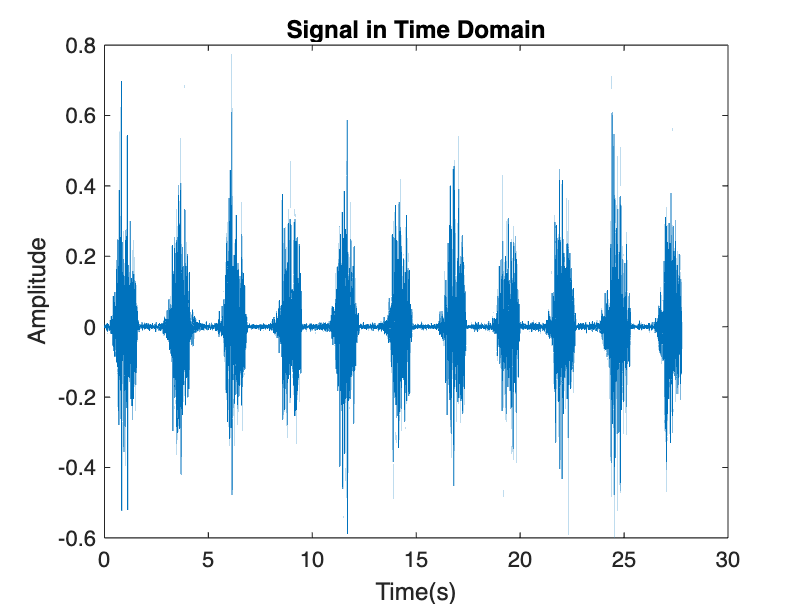

load('emg1.mat');

fs = 360; %Hz
t=linspace(0,length(emg1)/fs,length(emg1));
figure()
plot(t,emg1);
title('Signal in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');


figure()
f=linspace(-fs/2,fs/2,length(emg1));
fft_emg1 = fftshift(abs(fft(emg1)))

fft_emg1 =     0.0264
    0.0264
    0.0264
    0.0264
    0.0264
    0.0264
    0.0264
    0.0264
    0.0264
    0.0264


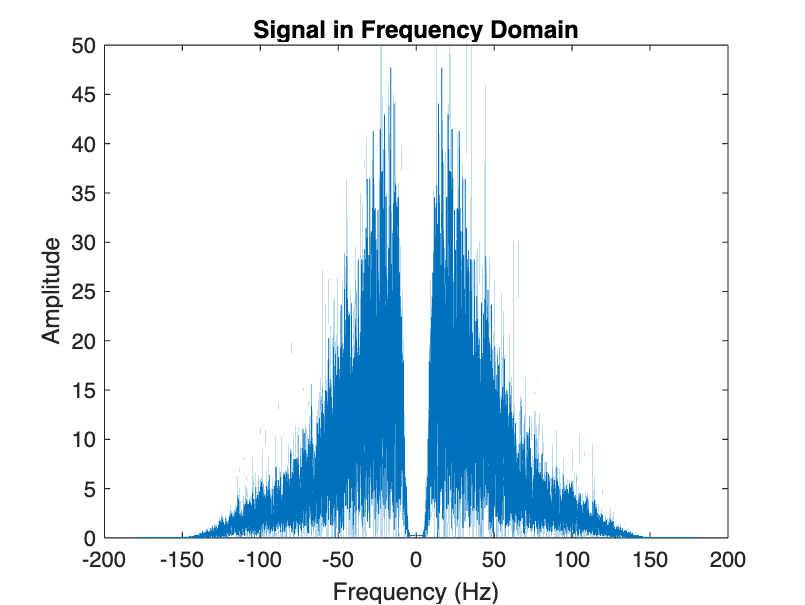


plot(f,fft_emg1);
title('Signal in Frequency Domain'); 
xlabel('Frequency (Hz)');
ylabel('Amplitude');

il segnale presenta di nuovo dei picchi a  +-60 Hz. in più e visibile una baseline wander.

Generate the artefacts and sum them to the original signals:

% powerline = pl
A_pl = 1;
f_pl = 60;
pl = A_pl*sin(2*pi*f_pl*t);

% baseline = bl
A_bl = 0.8;
f_bl = 0.3;
bl = A_bl*sin(2*pi*f_bl*t);

% ecg with artifacts
emg_sum = emg1 + pl' + bl';

Use the function add_noise.m to add white gaussian noise to the signals, with a SNR = 20dB.

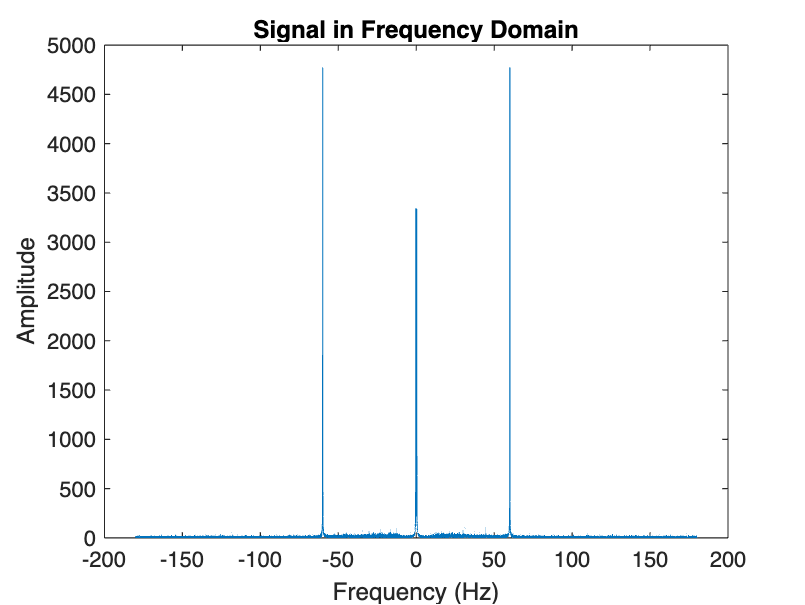

SNR = 20; %dB
emg_sum_noise = addNoise(emg_sum, t, SNR);
fft_emg_sum_noise = fftshift(abs(fft(emg_sum_noise)));

% figure()
% plot(t,emg_sum_noise);
% title('Signal in Time Domain');
% xlabel('Time(s)'); 
% ylabel('Amplitude');

figure()
plot(f,fft_emg_sum_noise);
title('Signal in Frequency Domain'); 
xlabel('Frequency (Hz)');
ylabel('Amplitude');